% Task 3
clear all
help filter

 filter One-dimensional digital filter.
    Y = filter(B,A,X) filters the data in vector X with the
    filter described by vectors A and B to create the filtered
    data Y.  The filter is a "Direct Form II Transposed"
    implementation of the standard difference equation:
 
    a(1)*y(n) = b(1)*x(n) + b(2)*x(n-1) + ... + b(nb+1)*x(n-nb)
                          - a(2)*y(n-1) - ... - a(na+1)*y(n-na)
 
    If a(1) is not equal to 1, filter normalizes the filter
    coefficients by a(1). 
 
    filter always operates along the first non-singleton dimension,
    namely dimension 1 for column vectors and non-trivial matrices,
    and dimension 2 for row vectors.
 
    [Y,Zf] = filter(B,A,X,Zi) gives access to initial and final
    conditions, Zi and Zf, of the delays.  Zi is a vector of length
    MAX(LENGTH(A),LENGTH(B))-1, or an array with the leading dimension 
    of size MAX(LENGTH(A),LENGTH(B))-1 

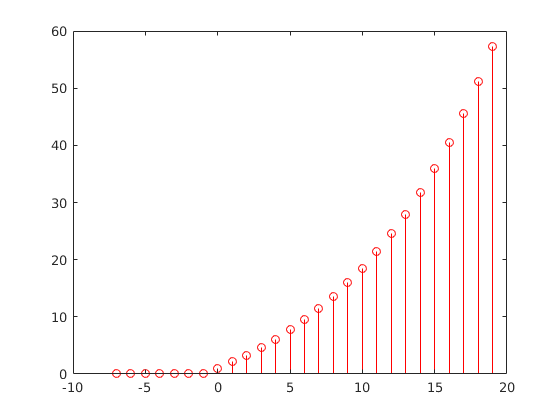

u = [zeros(1,7),ones(1,20)];
n=-7:19;
b=1;
a=[1 -1.1];
y=filter(b,a,u);
stem(n,y,'r')

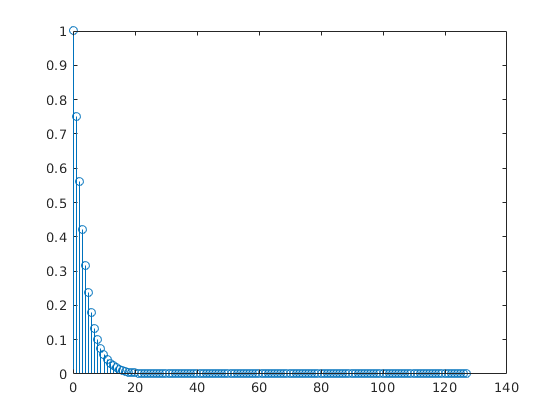

% Task 4
clear all

delta=[1,zeros(1,127)];
n=0:127;
a=[1 -0.75];
b=[1];
y1=filter(b,a,delta);
stem(n,y1)

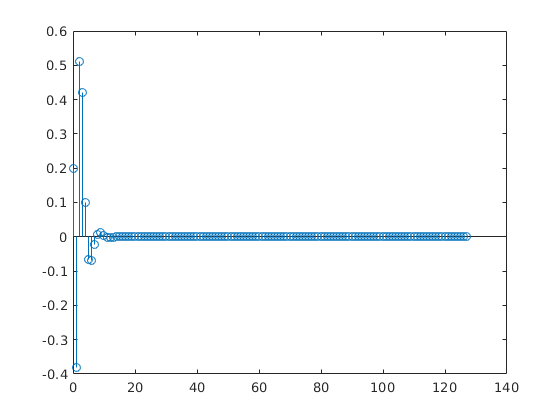


a1=[1 -0.6 0.3];
b1=[0.2 -0.5 0.8];
y2=filter(b1,a1,delta);
stem(n,y2)

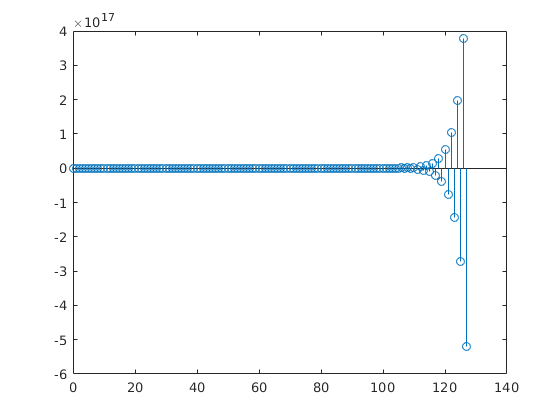


a2=[1 0.8 -0.8];
b2=[1 0.5 1.25];
y3=filter(b2,a2,delta);
stem(n,y3)

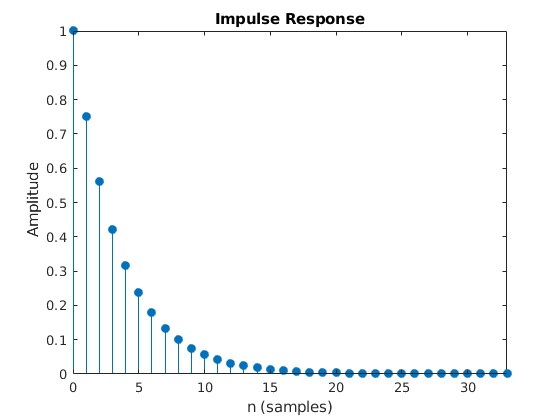

% Task 5
clear all 

delta=[1,zeros(1,127)];
n=0:127;

a=[1 -0.75];
b=[1];
impz(b,a)

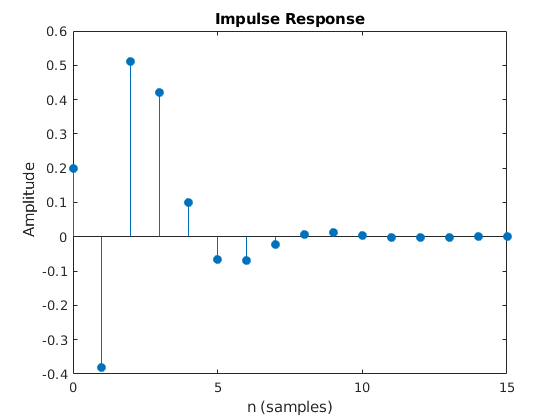


a1=[1 -0.6 0.3];
b1=[0.2 -0.5 0.8];
impz(b1,a1)

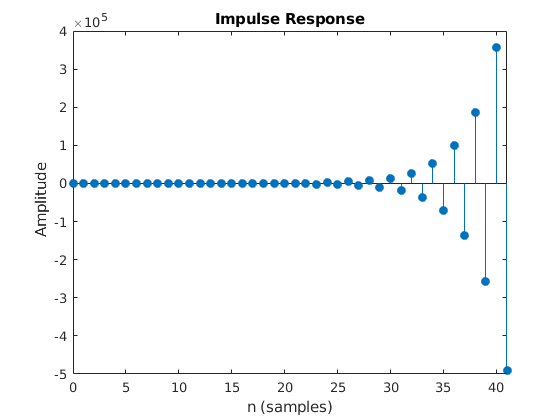


a2=[1 0.8 -0.8];
b2=[1 0.5 1.25];
impz(b2,a2)